# GReS Mesh input tutorial

cd(strcat(gres_root,'/Tutorial/01_meshInput'))

## Introduction

This tutorial introduces you to the basic GReS features to input a mesh, visualize it and manage the output of a simple simulation. 

## VTK file format

GReS supports two mesh file formats, `.vtk and .msh.` In this example, you will see how to read a mesh representing a simple cube. The [VTK](https://vtk.org/doc/nightly/html/index.html) (Visualization ToolKit) format is a widely used format for storing mesh and scientific data. It supports both ASCII and binary encoding and can represent structured and unstructured meshes. It is especially well-suited for visualization with tools such as ParaView or VisIt. The `.vtk` files can include point coordinates, connectivity (cells), cell types, and optional scalar or vector data for post-processing or visualization. Here is an example of a simple VTK file [Box.vtk](matlab:open('./Mesh\Box.vtk')).

**HEADER**

The file begins with a standard VTK header:

**In the current version of the code, this is the only admitted header for a vtk file. If you try to input a file where the above informations are different, GReS will throw an error.**

**POINTS**

This section lists 8 vertices deifning the corners of the cube, each with x, y, z coordinates:

**CELLS**

There are 3 cells:

The first two are quadrilaterals (4-node faces).

The third is a hexahedron (8-node volume).

The second number, 19, is the total number of integers appearing in the section:

3 cell definitions: (1×5) + (1×5) + (1×9) = 19 integers

**CELL_TYPES** 

This section characterizes each cell with an integer corresponding to the shape.

9 = quadrilateral (used for surfaces)

12 = hexahedron (used for the volume)

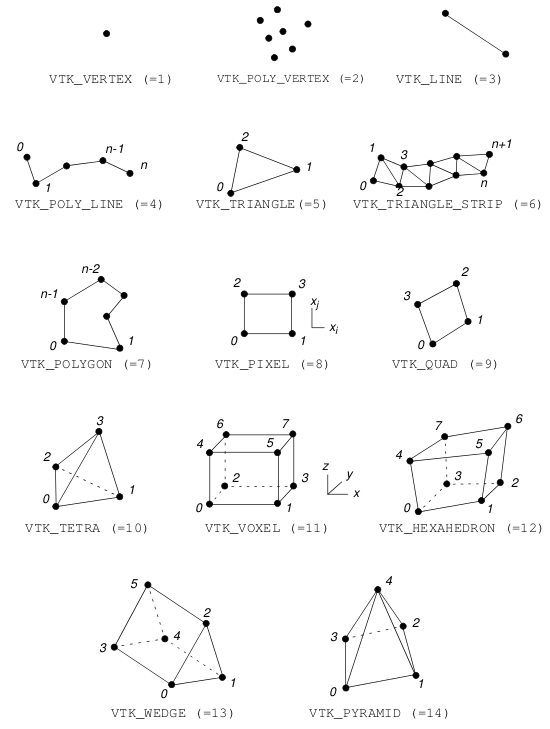

**CELL_DATA**

This scalar field assigns an ID to each cell.

The top and bottom faces have different IDs (1 and 2). The volume has ID 1.

These IDs are very useful to identify different regions of the grid where to impose boundary condition. 

## MSH file format

The .msh format is the native format of [GMSH](https://gmsh.info/doc/texinfo/gmsh.html), a powerful and open-source mesh generator. For the unit cube shown before, this is what the input file looks like.

**GReS only supports .msh file of version 2.2, which is not the latest one. **

We refer the user to the Gmsh tutorial for a detailed description of the .msh file format and how to use it for generating a grid. Note that the `.msh` file supports name for the cell or surface region under the `$PhysicalNames` section

## Reading a mesh in GReS

To read a mesh, you first need to create a `Mesh` object.

msh = Mesh();

If we print the object

msh

msh =   Mesh with properties:

               nDim: 0
             nNodes: 0
             nCells: 0
          nSurfaces: 0
             nEdges: 0
        coordinates: []
              cells: []
            cellTag: []
           nCellTag: []
       cellNumVerts: []
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: []
         surfaceTag: []
        nSurfaceTag: []
    surfaceNumVerts: []
              edges: []
            edgeTag: []
       edgeNumVerts: []
           cartGrid: 0
        cellRegions: []
     surfaceRegions: []
        cellVTKType: []
     surfaceVTKType: []
        edgeVTKType: []
           meshType: 'Unstructured'


we see that this object contain numerous properties still to be defined. 

To populate this properties, call the `importMesh() method `with the name of the mesh file.

msh.importMesh('Mesh/Box.vtk');

The file name must have either '.vtk' or '.msh' extension, so that GReS knows how to read the file. The path to the file is always relative to the location of the main file.

*Under the hood, GReS is using compiled C++ *[*mex function*](https://www.mathworks.com/help/matlab/call-mex-file-functions.html)* to read the grid. Take a look at the Setup tutorial to see how to compile c++ code and produce mex files before starting using it.*

Now print again the msh object

msh

msh =   Mesh with properties:

               nDim: 3
             nNodes: 8
             nCells: 1
          nSurfaces: 2
             nEdges: 0
        coordinates: [8×3 double]
              cells: [1 2 3 4 5 6 7 8]
            cellTag: 1
           nCellTag: 1
       cellNumVerts: 8
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2×4 double]
         surfaceTag: [2×1 double]
        nSurfaceTag: 2
    surfaceNumVerts: [2×1 double]
              edges: []
            edgeTag: [0×1 double]
       edgeNumVerts: [0×1 double]
           cartGrid: 0
        cellRegions: []
     surfaceRegions: []
        cellVTKType: 12
     surfaceVTKType: [2×1 double]
        edgeVTKType: [0×1 double]
           meshType: 'Unstructured'


The mesh is a 3D mesh (`nDim=3`) with 8 nodes, 1 cell and 2 surfaces. Notice the difference between the 6 geometrical surfaces of the cube and the 2 surfaces defined in Box.vtk.

`coordinates` contains the three coordinates of the nodes, while `cells` is the connectivity matrix listing the nodes belonging to each cell. Here, the matrix reduces to only a row vector since only one cell is defined. `surfaces` contains the topological information of the cells.

The information delivered by the CELL_DATA section is stored in the vectors `cellTag` and` surfaceTag`. CELL TYPE section of the vtk file is stored in the vectors `cellVTKType` and` surfaceVTKType`. 

Let's now import the .msh version of the grid and see the differences.

msh.importMesh('Mesh/Box.msh');
msh

msh =   Mesh with properties:

               nDim: 3
             nNodes: 8
             nCells: 1
          nSurfaces: 2
             nEdges: 0
        coordinates: [8×3 double]
              cells: [1 2 3 4 5 6 7 8]
            cellTag: 1
           nCellTag: 1
       cellNumVerts: 8
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2×4 double]
         surfaceTag: [2×1 double]
        nSurfaceTag: 2
    surfaceNumVerts: [2×1 double]
              edges: []
            edgeTag: [0×1 double]
       edgeNumVerts: [0×1 double]
           cartGrid: 0
        cellRegions: [1×1 struct]
     surfaceRegions: [1×1 struct]
        cellVTKType: 12
     surfaceVTKType: [2×1 double]
        edgeVTKType: [0×1 double]
           meshType: 'Unstructured'


As expected, all the information are the same. You may notice that the `cellRegions` and `surfaceRegion` properties are empty. Although they do not have any practical importance in a GReS simulation, they may be useful for the user to see to which part of the grid each tag is referring to. In order to set them to match the $PhysicalNames, use the following method to read the mesh. 

msh.importGMSHmesh('Mesh/Box.msh');
msh

msh =   Mesh with properties:

               nDim: 3
             nNodes: 8
             nCells: 1
          nSurfaces: 2
             nEdges: 0
        coordinates: [8×3 double]
              cells: [1 2 3 4 5 6 7 8]
            cellTag: 1
           nCellTag: 1
       cellNumVerts: 8
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2×4 double]
         surfaceTag: [2×1 double]
        nSurfaceTag: 2
    surfaceNumVerts: [2×1 double]
              edges: []
            edgeTag: [0×1 double]
       edgeNumVerts: [0×1 double]
           cartGrid: 0
        cellRegions: [1×1 struct]
     surfaceRegions: [1×1 struct]
        cellVTKType: 12
     surfaceVTKType: [2×1 double]
        edgeVTKType: [0×1 double]
           meshType: 'Unstructured'


## A more advanced example

Let's now import a more complicated grid, the one used in the [DeepAquifer](matlab:open('..\..\Tests\Deep_Aquifer\ReservoirTest_Hexa.msh')) test case. 

mshAdvanced = Mesh();
mshAdvanced.importMesh('Mesh/Reservoir.msh')
mshAdvanced

mshAdvanced =   Mesh with properties:

               nDim: 3
             nNodes: 3509
             nCells: 2800
          nSurfaces: 2120
             nEdges: 0
        coordinates: [3509×3 double]
              cells: [2800×8 double]
            cellTag: [2800×1 double]
           nCellTag: 3
       cellNumVerts: [2800×1 double]
       cellCentroid: []
    surfaceCentroid: []
         cellVolume: []
        surfaceArea: []
           surfaces: [2120×4 double]
         surfaceTag: [2120×1 double]
        nSurfaceTag: 5
    surfaceNumVerts: [2120×1 double]
              edges: []
            edgeTag: []
       edgeNumVerts: []
           cartGrid: 0
        cellRegions: [1×1 struct]
     surfaceRegions: [1×1 struct]
        cellVTKType: [2800×1 double]
     surfaceVTKType: [2120×1 double]
        edgeVTKType: []
           meshType: 'Unstructured'


Check out the workspace to inspect the properties of `mshAdvanced`. This object contains many `cellTag` and `surfaceTag`.